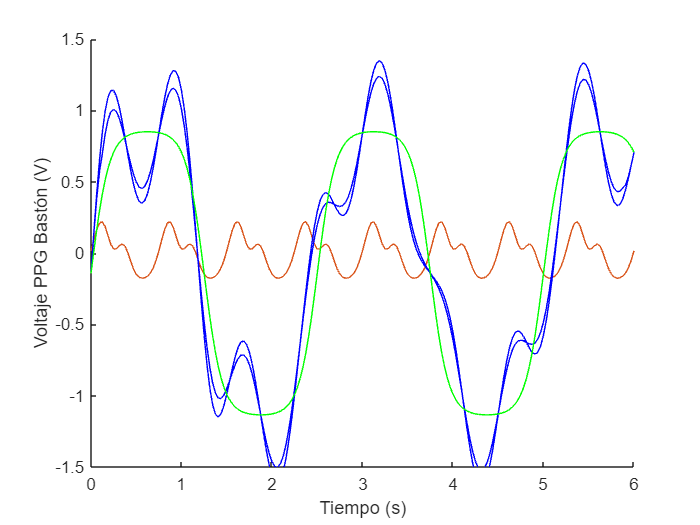

figure
hold on

fs=32;
x=0:1/fs:6;
y1=modeloFSR(x,0,1/2.5);
y2_=0.5*sin(x*(2*pi)*80/60);
y2=modeloPPG(x, 0, 80/60);
y=y1+y2_;



plot(x,y2,'Color',[0.8500, 0.3250, 0.0980])
%plot(x,y2_,'Color',[0, 0, 1])
%plot(x,smooth(y,1/3*fs),'Color',[0, 0, 1])
plot(x,y,'Color',[0, 0, 1])


plot(x,y1,'Color',[0, 1, 0])

xlabel("Tiempo (s)")
ylabel("Voltaje PPG Bastón (V)")
ylim([-1.5,1.5])

%legend(["Pulsera","Bastón","FSR*"], 'FontSize', 20)

function y = modeloPPG(t, t_inic, frec_ondas)

params = [0.5, 0.2, 0.15, ...     % Pico sistolico
          0.2, 0.3, 0.1, ...   % Valle dicroto
          0.2, 0.48, 0.1];     % Pico diastolico
    A_s = params(1); t_s = params(2)/frec_ondas; sigma_s = params(3)/frec_ondas;
    A_o = params(4); t_o = params(5)/frec_ondas; sigma_o = params(6)/frec_ondas;
    A_d = params(7); t_d = params(8)/frec_ondas; sigma_d = params(9)/frec_ondas;

    y = zeros(1,length(t));
    
    for i = (t_inic:1/frec_ondas:t(end)+1/frec_ondas)-1/frec_ondas
    y = y...
      + A_s * exp(-(t - t_s -i).^2 / (2 * sigma_s^2)) ...
      - A_o * exp(-(t - t_o -i).^2 / (2 * sigma_o^2)) ...
      + A_d * exp(-(t - t_d -i).^2 / (2 * sigma_d^2));
    end

    y=y-mean(y);
end
function y = modeloFSR(t, t_inic, frec_ondas)

    y = zeros(1,length(t));
    
    m=10;
    A=2;
    for i = (t_inic:1/frec_ondas:t(end)+1/frec_ondas)-1/frec_ondas
    y = y...
      + A./(1 + exp(-m*(t - i - t_inic))) - A./(1 + exp(-m*(t - i - t_inic - 1/frec_ondas/2)));
    end

    y=y-mean(y);
end